## Analyzing Passive Acoustic Data with MHKiT

The following example illustrates how to read and analyze some basic parameters for passive acoustics data. Functionality to analyze .wav files recorded using hydrophones has been integrated into MHKiT to support analysis based on the IEC-TS 62600-40 standard.

The standard workflow for passive acoustics analysis is as follows:

- Import .wav file

- Calibrate data

- Calculate spectral density

- Calculate other parameters

- Create plots

### Read in Hydrophone Measurements

All hydrophone .wav files can be read in MHKiT using a base function called `read_hydrophone` from the `acoustics.io` submodule. Because the sampling frequency is so fast, measurements are stored in the lowest memory format possible and need to be scaled and transformed to return the measurements in units of voltage or pressure.

The `read_hydrophone` function scales and transforms raw measurements given a few input parameters. Most parameters needed to convert the raw data are stored in the native .wav format header blocks, but two, the "peak_voltage" of the sensor’s analog-to-digital converter (ADC) and file “start_time” (usually stored in the filename) are required.

Two other inputs, the hydrophone “sensitivity” and an amplifier “gain” can also be input. If a sensitivity value is provided, the function will convert voltage to pressure; otherwise the sensitivity(ies) can be provided later using a calibration curve. Gain should be provided if the instrument utilizes an amplifier gain (typically for custom hydrophone builds), which is then added to the sensitivity.

filename = "examples/data/acoustics/RBW_6661_20240601_053114.wav";
peak_voltage = 3; % V
sensitivity = -177; % db
gain = 0;
start_time= "2024-06-01T05:31:14";
P = read_hydrophone(filename,peak_voltage,sensitivity,gain,start_time)

P = struct with fields:
           time: [01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    …    ] (1×30720000 datetime)
           data: [30720000×1 double]
          units: 'Pa'
    sensitivity: 1.4125e-09
      valid_min: -2.1238e+03
      valid_max: 2.1238e+03
             fs: 512000
       filename: "RBW_6661_20240601_053114.wav"


“Smart” hydrophones are those where the hydrophone element, pre-amplifier board, ADC, motherboard and memory card are sold in a single package. Companies that sell these often store metadata in the .wav file header, and MHKiT has a couple of wrapper functions for these hydrophones.

OceanSonics icListen and OceanInstruments Soundtrap are two common smart hydrophone models, with examples as follows.

For icListen datafiles, only the filename is necessary to provide to return file contents in units of pressure. The stored sensitivity calibration value can be overridden by setting the “sensitivity” input, and to return measurements in units of voltage, set `sensitivity` to empty and `use_metadata` to false.

P = read_iclisten(filename) % get sound pressure

P = struct with fields:
                     time: [01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    …    ] (1×30720000 datetime)
                     data: [30720000×1 double]
                    units: 'Pa'
              sensitivity: 1.4125e-09
                valid_min: -2.1238e+03
                valid_max: 2.1238e+03
                       fs: 512000
                 filename: "RBW_6661_20240601_053114.wav"
            serial_number: 'icListen HF #6661'
          bits_per_sample: 24
             peak_voltage: 3
                 humidity: '24.0 % RH'
              temperature: '8.6 deg C'
            accelerometer: 'Acc(-980,-18,141)'
             magnetometer: 'Mag(3603,3223,-598)'
    count_at_peak_voltage: '8388608 = Max Count'
             sequence_num: '2589798400000 = Seq #'


V = read_iclisten(filename, [], false) % get raw voltage only

V = struct with fields:
                     time: [01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    01-Jun-2024 05:31:14    …    ] (1×30720000 datetime)
                     data: [30720000×1 double]
                    units: 'V'
                valid_min: -3
                valid_max: 3
                       fs: 512000
                 filename: "RBW_6661_20240601_053114.wav"
            serial_number: 'icListen HF #6661'
          bits_per_sample: 24
             peak_voltage: 3
                 humidity: '24.0 % RH'
              temperature: '8.6 deg C'
            accelerometer: 'Acc(-980,-18,141)'
             magnetometer: 'Mag(3603,3223,-598)'
    count_at_peak_voltage: '8388608 = Max Count'
             sequence_num: '2589798400000 = Seq #'


For Ocean Instruments Soundtrap datafiles, the filename and sensitivity should be provided to return the measurements in units of pressure. If the hydrophone has been calibrated, set the sensitivity to empty to return the measurements in units of voltage.

sfile = "examples/data/acoustics/6247.230204150508.wav";
P = read_soundtrap(sfile, -177)

P = struct with fields:
           time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    …    ] (1×28800672 datetime)
           data: [28800672×1 double]
          units: 'Pa'
    sensitivity: 1.4125e-09
      valid_min: -707.9458
      valid_max: 707.9458
             fs: 96000
       filename: "6247.230204150508.wav"


V = read_soundtrap(sfile, [])

V = struct with fields:
         time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    …    ] (1×28800672 datetime)
         data: [28800672×1 double]
        units: 'V'
    valid_min: -1
    valid_max: 1
           fs: 96000
     filename: "6247.230204150508.wav"


### Mean Square Sound Pressure Spectral Density

After the .wav file is read in, either in units of pressure or voltage, we calculate the mean square sound pressure spectral density (SPSD) of the timeseries using `sound_pressure_spectral_density`. This splits the timeseries into windows and uses fast Fourier transforms to convert the raw measurements into the frequency domain, with units of Pa^2/Hz or V^2/Hz depending on the input. The function takes the original datafile, the hydrophone’s sampling rate (“fs”), which is stored as an attribute of the measurement timeseries, and a window size (“bin_length”) in seconds as input.

The IEC-40 considers an acoustic sample to have a length of 1 second, so we’ll set the bin length as such here.

% create mean square spectral densities using 1 second bins
spsd = sound_pressure_spectral_density(V, V.fs, 1)

spsd = struct with fields:
       data: [48000×599 double]
       time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:09    04-Feb-2023 15:05:09    04-Feb-2023 15:05:10    04-Feb-2023 15:05:10    04-Feb-2023 15:05:11    04-Feb-2023 15:05:11    04-Feb-2023 15:05:12    …    ] (1×599 datetime)
       freq: [48000×1 double]
       name: "Mean Square Sound Pressure Spectral Density"
      units: "V^2/Hz"
         fs: 96000
       nbin: "1 s"
    overlap: "50%"
       nfft: 96000


### Applying Calibration Curves

For conducting scientific-grade analysis, it is critical to use calibration curves to correct the SPSD calculations. Hydrophones should be calibrated (i.e., a sensitivity calibration curve should be generated for a hydrophone) every few years. The IEC-40 asks that a hydrophone be calibrated both before and after the test deployment.

A calibration curve consists of the hydrophone’s sensitivity (in units of dB rel 1V^2/uPa^2) vs frequency and should be applied to the spectral density we just calculated.

The easiest way to apply a sensitivity calibration curve in MHKiT is to first copy the calibration data into a CSV file, where the left column contains the calibrated frequencies and the right column contains the sensitivity values. Here we use the function in the following codeblock to read in a CSV file created with the column headers “Frequency” and “AnalogSensitivity”.

% read in csv table
sense_table = readtable("examples\data\acoustics\6247_calibration.csv")

sense_table = 40×2 table
    Frequency    AnalogSensitivity
    _________    _________________

          1           -223.49     
      1.183            -220.8     
      1.399           -218.13     
      1.655           -215.41     
      1.958           -212.68     
      2.316           -209.91     
       2.74           -207.12     
      3.241           -204.29     
      3.834           -201.45     
      4.535           -198.58     
      5.364           -195.69     
      6.345           -192.79     
      7.506           -189.85     
      8.879            -186.9     
       10.5           -183.93     
      12.42           -180.93     


Now, lets simplify the table into a matrix of two columns where the first is frequency and the second holds the calibration values. Once we have the calibration data in a matrix, we can apply that to the SPSD using the `apply_calibration` function. Calibration curves typically do not cover the entire range of the hydrophone, so this function will linearly interpolate the missing values. A fill_value can be provided to extrapolate outside of the calibrated frequencies.

sense_curve = table2array(sense_table);
fill_Sf = sense_curve(end, 2); % use last value in curve for higher frequencies
spsd_cal = apply_calibration(spsd, sense_curve, fill_Sf)

spsd_cal = struct with fields:
       data: [48000×599 double]
       time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:09    04-Feb-2023 15:05:09    04-Feb-2023 15:05:10    04-Feb-2023 15:05:10    04-Feb-2023 15:05:11    04-Feb-2023 15:05:11    04-Feb-2023 15:05:12    …    ] (1×599 datetime)
       freq: [48000×1 double]
       name: "Calibrated Sound Pressure Spectral Density"
      units: "Pa^2/Hz"
         fs: 96000
       nbin: "1 s"
    overlap: "50%"
       nfft: 96000


### Mean Square Sound Pressure Spectral Density Level

We can use the function `sound_pressure_spectral_density_level` to calculate the mean square sound pressure spectral density levels (SPSDLs) from the calibrated SPSD. This function converts absolute pressure into relative pressure in log-space, the traditional means with which we measure sound, in units of decibels relative to 1 uPa [dB rel 1 uPa], the standard for underwater sound. 

Sidenote: Sound in air is measured in decibels relative to 20 uPa, the minimum sound pressure humans can hear. To convert between [dB rel 1 uPa] and [dB rel 20 uPa], one simply needs to subtract 26 dB from the [dB rel 1 uPa] value.

spsdl = sound_pressure_spectral_density_level(spsd_cal)

spsdl = struct with fields:
       data: [48000×599 double]
       time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:09    04-Feb-2023 15:05:09    04-Feb-2023 15:05:10    04-Feb-2023 15:05:10    04-Feb-2023 15:05:11    04-Feb-2023 15:05:11    04-Feb-2023 15:05:12    …    ] (1×599 datetime)
       freq: [48000×1 double]
       name: "Sound Pressure Spectral Density Level"
      units: "dB re 1 uPa^2/Hz"
         fs: 96000
       nbin: "1 s"
    overlap: "50%"
       nfft: 96000


Now that the SPSDL is calculated, we can create spectrograms, or waterfall plots, using the `plot_spectrogram` function in the graphics submodule. While spectrograms aren't required by the IEC-40, they are useful to do quality control so we can avoid using contaminated soundbytes in further analysis (i.e., we'd remove the boat noise shown here from further analysis of a marine energy device).

To do this, we'll give the function the minimum and maximum frequencies to plot, define the colormap, and provide min and max ranges of the colorbar. For these measurements, we're setting fmin = 10 Hz, the minimum specified by the IEC-40, and fmax = 48,000 Hz, the Nyquist frequency for these data. 

Note, the IEC-40 requires a maximum frequency of 100,000 Hz, so a hydrophone capable of sampling faster than 200,000 Hz should be used for IEC testing.

% show Nyquist frequency (max in frequency vector)
max(spsdl.freq)

ans = 48000

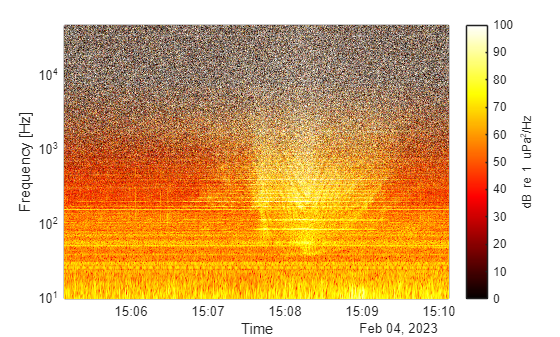

fmin = 10;
fmax = 48000;

% create high resolution spectogram
plot_spectogram(spsdl, fmin, fmax, 'hot', 0, 100)

If you see something interesting in the spectrogram, the next step you should do is listen to the .wav file. This can tell you a lot about what you're looking at. If you listen to this file, you'll hear the boat cruising by around 3 minutes in. To do this, we will utilize MATLAB's built-in functions.

player = audioplayer(P.data, P.fs); % define audioplayer with data
%play(player) % uncomment to listen
%stop(player) % uncomment to stop

### IEC-40 Stats

The IEC-40 requires a few aggregate statistics for characterizing the sound of marine energy devices. For the first, the IEC-40 asks for plots showing the 25%, 50%, and 75% quantiles of the SPSDL during specific marine energy device states. For current energy devices, the IEC-40 requires 10 SPSDL samples at a series of turbine states (braked, freewheel, 25% power, 50% power, 75% power, 100% power). For wave energy devices, the spec requires 30 SPSDL samples in each wave height and period bin observed.

For this example notebook we'll keep it simple and use a random set of 30 samples and collate them together. Typically, one will pick and choose which 1 second samples to collate together and analyze. Then we can find the median and quantiles of those 30 samples.

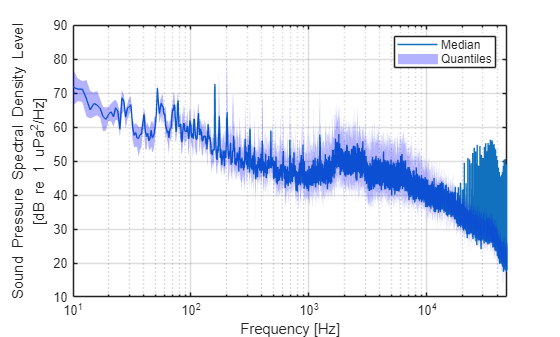

spsdl_median = spsdl;
samples = randperm(length(spsdl.data(1,:)),30);
temp = spsdl.data(:,samples);

spsdl_median.data = median(temp,2);
spsdlq25 = quantile(temp, 0.25, 2);
spsdlq75 = quantile(temp, 0.75, 2);

plot_spectra(spsdl_median,fmin,fmax)
patch([spsdl.freq' fliplr(spsdl.freq')], [spsdlq25' fliplr(spsdlq75')],'b','EdgeColor', 'none', 'FaceAlpha', 0.3)
legend('Median','Quantiles')

### Window Aggregating

If desired, one can group a series of measurements into blocks of time, though this isn't required by the IEC-40. In the following block, we'll take our 5 minutes of measurements, `time_aggregate` them into 30 second intervals, and find the median, 25% and 75% quantiles of each interval. We then plot the stats of the median parameters.

window = 30; %seconds
method = "median";
spsdl_time = time_aggregate(spsdl, window, method)

spsdl_time = struct with fields:
     data: [48000×10 double]
     time: [04-Feb-2023 15:05:23    04-Feb-2023 15:05:53    04-Feb-2023 15:06:23    04-Feb-2023 15:06:53    04-Feb-2023 15:07:23    04-Feb-2023 15:07:53    04-Feb-2023 15:08:23    04-Feb-2023 15:08:53    04-Feb-2023 15:09:23    04-Feb-2023 15:09:53]
     freq: [48000×1 double]
    units: "dB re 1 uPa^2/Hz"
     name: "Sound Pressure Spectral Density Level"


We can then use the `plot_spectra` function in the graphics submodule to plot the median and quantiles of the first 30s window.

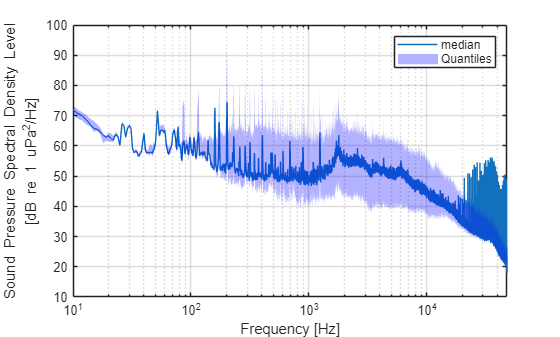

spsdl_med = spsdl_time;
spsdl_med.data = median(spsdl_time.data, 2);
spsdlq25 = quantile(spsdl_time.data, 0.25, 2);
spsdlq75 = quantile(spsdl_time.data, 0.75, 2);
% make plot
plot_spectra(spsdl_med, fmin, fmax)
patch([spsdl.freq' fliplr(spsdl.freq')], [spsdlq25' fliplr(spsdlq75')],'b','EdgeColor', 'none', 'FaceAlpha', 0.3)
legend(method,'Quantiles')

### Frequency Band Analysis

Frequency band analysis can be completed by grouping the data into specific frequency bands, called "band aggregating" here. In other words, instead of aggregating by the time dimension, we aggregate by the frequency dimension. The `band_aggregate` function operates by taking the SPSDL and grouping it based on a specified octave and octave base.

In the following codeblock, we use the same plotting function as above, but do so by creating the decidecade frequency bands (10th octave, octave base 10 => $10^{1/10}$). We'll calculate the median and quantiles of each sample, then take the median of each of those parameters. For the IEC-40, one will calculate these parameters for each device operating state (current energy converters) or wave state matrix (wave energy converters).

octave = [10, 10]; % [octave, octave base]
method = "median";
spsdl10 = band_aggregate(spsdl,octave,fmin,fmax,method)

spsdl10 = struct with fields:
     data: [38×599 double]
     freq: [10 12.5893 15.8489 19.9526 25.1189 31.6228 39.8107 50.1187 63.0957 79.4328 100 125.8925 158.4893 199.5262 251.1886 316.2278 398.1072 501.1872 630.9573 794.3282 1.0000e+03 1.2589e+03 1.5849e+03 1.9953e+03 2.5119e+03 3.1623e+03 … ] (1×38 double)
     time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:09    04-Feb-2023 15:05:09    04-Feb-2023 15:05:10    04-Feb-2023 15:05:10    04-Feb-2023 15:05:11    04-Feb-2023 15:05:11    04-Feb-2023 15:05:12    …    ] (1×599 datetime)
     name: "Sound Pressure Spectral Density Level"
    units: "dB re 1 uPa^2/Hz"


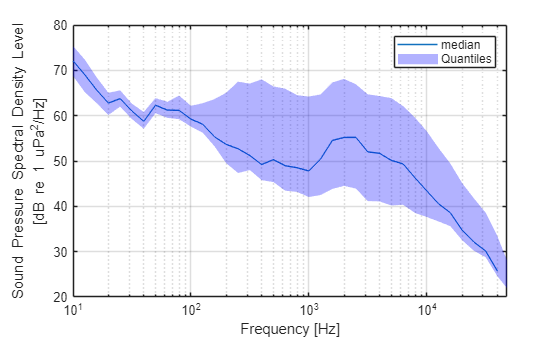

spsdl10m = spsdl10;
spsdl10m.data = median(spsdl10.data, 2);
spsdlq25 = quantile(spsdl10.data, 0.25, 2);
spsdlq75 = quantile(spsdl10.data, 0.75, 2);
% make plot
plot_spectra(spsdl10m, fmin, fmax)
patch([spsdl10.freq fliplr(spsdl10.freq)], [spsdlq25' fliplr(spsdlq75')],'b','EdgeColor', 'none', 'FaceAlpha', 0.3)
legend(method,'Quantiles')

The plot above shows significant spread in sound measurements at higher frequency due to the vessel noise, but less so at lower frequency. This mirrors what we can see in the sound pressure density level figure we first plotted.

You can further build on the results with more complicated statistical methods. In the following block of code, we find the empirical quantile function (the empirical version of the cumulative distribution function, CDF) of each decidecade frequency band and plot the decidecade band centered nearest to 160 Hz. 

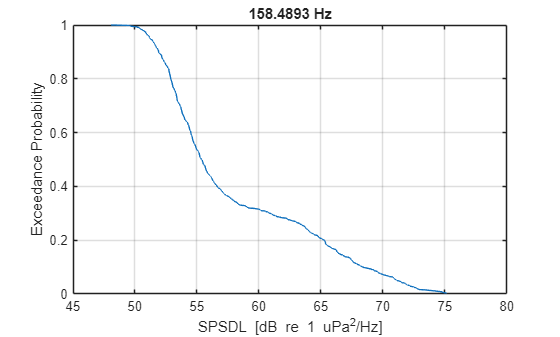

f = 160; % target frequency
[val, idxf] = min(abs(spsdl10.freq-f));
n = numel(spsdl10.data(1,:));
p = 1.0 - (0:(n-1))' / (n + 1);
x = sort(spsdl10.data(idxf,:));
plot(x,p)
xlabel('SPSDL [dB re 1 uPa^2/Hz]'); ylabel("Exceedance Probability"); 
title(strcat(num2str(spsdl10.freq(idxf))," Hz"))
grid on;

### Sound Pressure Level

The IEC-40 has two requirements considering calculations of sound pressure level (SPL). We'll first calculate the SPL over the full frequency range of the turbine and/or hydrophone using the function `sound_pressure_level`. First, however, note that the IEC-40 asks that the range be set from 10 to 100,000 Hz. The lower limit can be increased due to flow noise or low frequency signal loss due to shallow water. 

#### Shallow water cutoff frequency

Low frequency sound is absorbed into the seabed in shallow water depths. We can use the function `minimum_frequency` to get an approximation of what our minimum frequency should be. This approximation uses the water depth, estimates of the in-water sound speed, and sea/riverbed sound speed to determine what the cutoff frequency will be. The difficult part with this approximation is figuring out the speed of sound in the bed material, which generally ranges from 1450-1800 m/s. 

This function should only be used as a rough approximation and sanity check if significant attenuation is seen at various low frequencies and harmonics.

depths = [1, 5, 10, 20, 40, 80];
c = 1500; % speed of sound in water
c_seabed = 1700; % speed of sound in seabed
fmin = minimum_frequency(depths, c, c_seabed);
% print out min freq for corresponding depths
for i = 1:length(depths)
    fprintf('%d m = %.1f Hz\n', depths(i), fmin(i));
end

1 m = 796.9 Hz
5 m = 159.4 Hz
10 m = 79.7 Hz
20 m = 39.8 Hz
40 m = 19.9 Hz
80 m = 10.0 Hz


Though the IEC-40 says we should default to a minimum frequency of 10 Hz, as you can see above, unless we're measuring from a depth of around 80 +/- 10 m, our minimum frequency should be higher. One can play around with the bed soundspeed to see how these change with varying bed densities/compositions.

#### Flow noise

Flow noise, or psuedo-sound, is the other reason to increase the minimum frequency of our SPL measurements. Flow noise is caused by one of three things: turbulence advected past the hydrophone element, turbulence caused by the hydrophone element, and the sensitivity of the hydrophone element to temperature inhomogeneities in the advected flow. Flow noise is most noticeably apparent when flow speeds increase above 0.5 m/s, seen in spectrograms as a logarithmic increase in pressure with decreasing frequency.

The particular data shown here was measured in around 8-10 m of water, and a mix of mild flow noise below 20 Hz and low frequency attenutation below ~50 Hz can be seen in the spectrogram. We'll again use the Nyquist frequency of 48,000 Hz.

#### Cumulative SPL

Running the code block below, we can see our cumulative SPL start out at 86 dB and then peak at 125 dB as the boat drives by. If you haven't listened to the audio track, this peak SPL of 125 dB rel 1 uPa (underwater) is equivalent to 99 dB rel 20 uPa (air). For reference, the OSHA time limit for workers experiencing 100 dB rel 20 uPa of sound is 2 hours. Vessel traffic can be quite loud and is one of the largest contributors to noise in the marine environment.

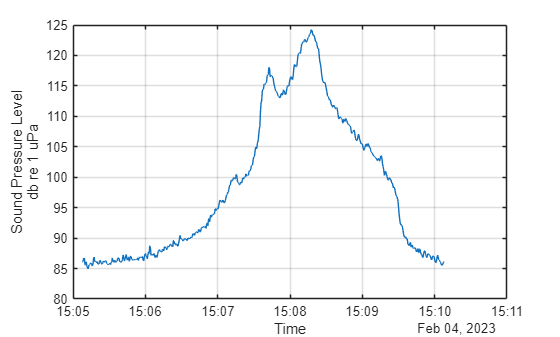

% sound pressure level
fmin = 50;
fmax = 48000;
spl = sound_pressure_level(spsd_cal, fmin, fmax);
% make figure
plot(spl.time,spl.data)
xlabel('Time'); ylabel({spl.name; spl.units}); grid on;

### Decidecade Sound Pressure Levels

The last stat that IEC-40 requests are the decidecade SPLs, where the SPL is calculated for each decidecade frequency band. Note that the IEC-40 labels these as synonymous the third-octave SPLs; while for some applications this may be true, mathematically they have different definitions. 

To explain, a true octave is a frequency band where the upper frequency is double (i.e., base 2) that of the lower frequency. Third octaves are often measured because mammals to have evolved to interpret sound at this bandwidth. The true one-third octave is a frequency band where the upper frequency is 2^(1/3) = 1.25992 times the lower frequency. The decidecade band referenced by the IEC-40 refers to the one-tenth octave of base 10, where the upper frequency is 10 times that of the lower frequency. Mathematically this means the decidecade band has a bandwidth of 10^(1/10) = 1.25892. So, when reporting frequency analysis, it is important to note both the octave and its bandwidth.

We can calculate the SPL in each decidecade band using the function `decidecade_sound_pressure_level`. This function uses the same calculation as `sound_pressure_level` above and runs it on each tenth octave band. It returns 1 SPL in each frequency band every timestamp. Boats are loud.

spl10 = decidecade_sound_pressure_level(spsd_cal, fmin, fmax)

spl10 = struct with fields:
     data: [31×599 double]
     freq: [50.0000 62.9463 79.2447 99.7631 125.5943 158.1139 199.0536 250.5936 315.4787 397.1641 500.0000 629.4627 792.4466 997.6312 1.2559e+03 1.5811e+03 1.9905e+03 2.5059e+03 3.1548e+03 3.9716e+03 5.0000e+03 6.2946e+03 7.9245e+03 … ] (1×31 double)
     time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:09    04-Feb-2023 15:05:09    04-Feb-2023 15:05:10    04-Feb-2023 15:05:10    04-Feb-2023 15:05:11    04-Feb-2023 15:05:11    04-Feb-2023 15:05:12    …    ] (1×599 datetime)
    units: 'db re 1 uPa'
     name: 'Decidecade Sound Pressure Level'


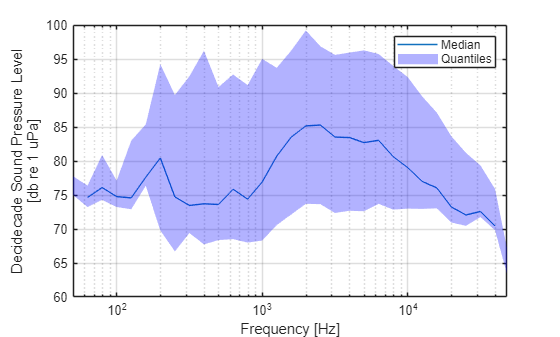

spl10m = spl10;
spl10m.data = median(spl10.data, 2);
splq25 = quantile(spl10.data, 0.25, 2);
splq75 = quantile(spl10.data, 0.75, 2);
plot_spectra(spl10m, fmin, fmax)
patch([spl10.freq fliplr(spl10.freq)], [splq25' fliplr(splq75')],'b','EdgeColor', 'none', 'FaceAlpha', 0.3)
legend('Median','Quantiles')

### Third Octave Sound Pressure Level

One can also calculate the true 1/3 octave SPLs using `third_octave_sound_pressure_level` if desired. Note the results are quite similar to `decidecade_sound_pressure_level`.

spl3 = decidecade_sound_pressure_level(spsd_cal, fmin, fmax)

spl3 = struct with fields:
     data: [31×599 double]
     freq: [50.0000 62.9463 79.2447 99.7631 125.5943 158.1139 199.0536 250.5936 315.4787 397.1641 500.0000 629.4627 792.4466 997.6312 1.2559e+03 1.5811e+03 1.9905e+03 2.5059e+03 3.1548e+03 3.9716e+03 5.0000e+03 6.2946e+03 7.9245e+03 … ] (1×31 double)
     time: [04-Feb-2023 15:05:08    04-Feb-2023 15:05:08    04-Feb-2023 15:05:09    04-Feb-2023 15:05:09    04-Feb-2023 15:05:10    04-Feb-2023 15:05:10    04-Feb-2023 15:05:11    04-Feb-2023 15:05:11    04-Feb-2023 15:05:12    …    ] (1×599 datetime)
    units: 'db re 1 uPa'
     name: 'Decidecade Sound Pressure Level'


spl3m = spl3;
spl3m.data = median(spl3.data, 2);
splq25 = quantile(spl3.data, 0.25, 2);
splq75 = quantile(spl3.data, 0.75, 2);
plot_spectra(spl3m, fmin, fmax)
patch([spl3.freq fliplr(spl3.freq)], [splq25' fliplr(splq75')],'b','EdgeColor', 'none', 'FaceAlpha', 0.3)
legend('Median','Quantiles')

### Sound Exposure Level and Marine Mammal Weightings

While the IEC-40 does not have recommendations for sound exposure level (SEL), it is a better parameter for quantifying auditory stress/injury to organisms. Sound exposure level is a metric that quantifies sound pressure level relative to exposure duration, based on the idea that that the effects on an organism's hearing are the same for equivalent totals sound energy received - even if that energy was received at different rates. Numerically, an SPL of 190 dB re 1 uPa over a 1 second interval and an SPL 160 dB re 1 uPa for 1000 seconds both have a SEL of 190 dB re 1 uPa^2 s.

The National Marine Fisheries Service (NMFS) publishes auditory weighting functions for five groups of marine mammals. These weighting functions are designed to try to emulate the auditory sensitivity of each group to better predict auditory injury thresholds. They are mathematically equivalent to band-pass filters. A link to the latest recommendations from NMFS is [https://www.fisheries.noaa.gov/national/marine-mammal-protection/marine-mammal-acoustic-technical-guidance-other-acoustic-tools](https://www.fisheries.noaa.gov/national/marine-mammal-protection/marine-mammal-acoustic-technical-guidance-other-acoustic-tools).

The SEL function `sound_exposure_level` has a few inputs. One is the pressure spectral density (PSD) in Pa^2/Hz, found from `sound_pressure_spectral_density`. The 'n_bin' input to that function should be the same length of time as you want to calculate SEL for. If you would like to calculate the 24 hr SEL, you need 24 hours worth of data - the best way to do this and save computer RAM would be to calculate the PSD from each 1-5 minute individual file and then concatenate the PSD from each file together.

Set "group=None" to calculate the standard SEL. Set "group" to "LF" for 'low frequency' cetaceans; "HF" for 'high frequency' cetaceans; "VHF" for 'very high frequency' cetaceans; "PW" for phocid pinnepeds; and "OW" for otariid pinnepeds.

% five minute SEL
spsd_300s = sound_pressure_spectral_density(V, V.fs, 300);
% calibrate PSD
fill_Sf = sense_curve(end, 2); % use last value in curve for higher frequencies
spsd_300s = apply_calibration(spsd_300s, sense_curve, fill_Sf);

group = ["LF", "HF", "VHF", "PW", "OW"];
sel = sound_exposure_level(spsd_300s, [], fmin, fmax);
fprintf('Group-Standard SEL = %.1f\n', sel.data)

Group-Standard SEL = 136.9


for g = 1:length(group)
    sel = sound_exposure_level(spsd_300s, group(g), fmin, fmax);
    fprintf('Group-%s SEL = %.1f\n', group(g), sel.data)
end

Group-LF SEL = 136.1
Group-HF SEL = 133.6
Group-VHF SEL = 128.5
Group-PW SEL = 135.1
Group-OW SEL = 132.7
